# Plotting LIDAR Range Data

The code below sets up the robot object, loads a map, and parses the map file generate obstacle data structures. Previously these steps could be completed using the simulator app.

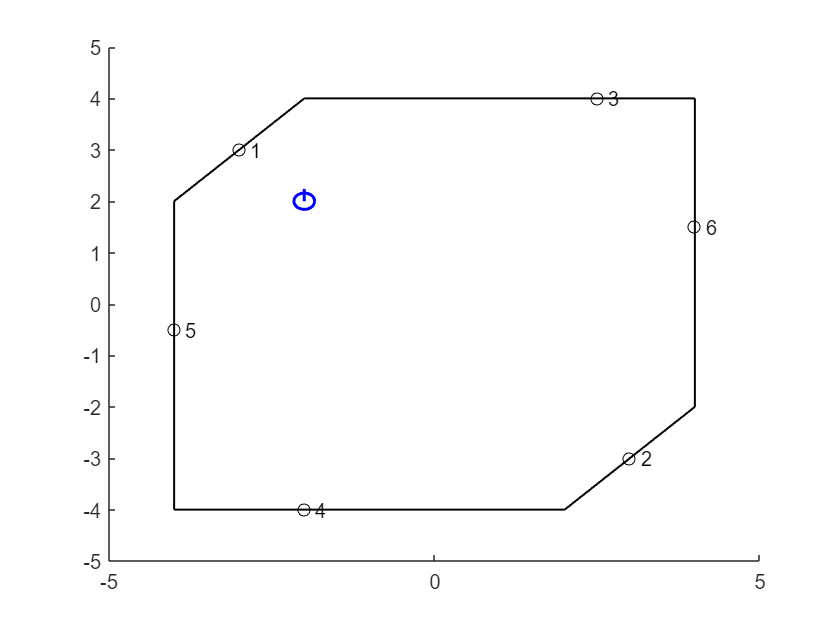

robotObj = CreateRobot_refactor(); % create an instance of the CreateRobot_refactor class
map = CreateRobot_refactor.loadMap("MAP1.txt"); % parse the map file and get the map struct with fields corresponding to the various obstacles
robotObj.setMapStart([-2,2,pi/2]); % set the pose of the robot
robotObj.plotScene(map); %plot map and show the robot pose in the map

% Get LIDAR Constants
%angRangeLidar = robotObj.angleRangeLidar;
rangeLidar = robotObj.rangeLidar;
numPtsLidar = robotObj.numPtsLidar;
angleData = robotObj.angleArray;

% Get LIDAR data. genLidar() returns a row vector with length = numPtsLid
distLidar= robotObj.genLidar(map); % use dot notation to call the object method, the lidar sensor needs to know where the walls are so pass the map struct to this method to simulate an accurate reading

Plot the LIDAR Data

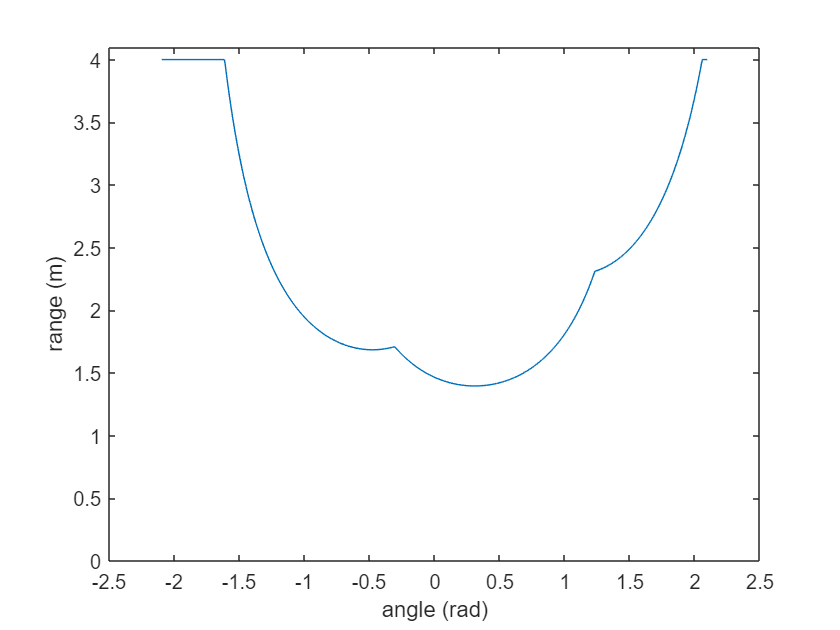


plot(angleData, distLidar); 
xlabel('angle (rad)')
ylabel('range (m)')
axis([-2.5 2.5 0 4.1])